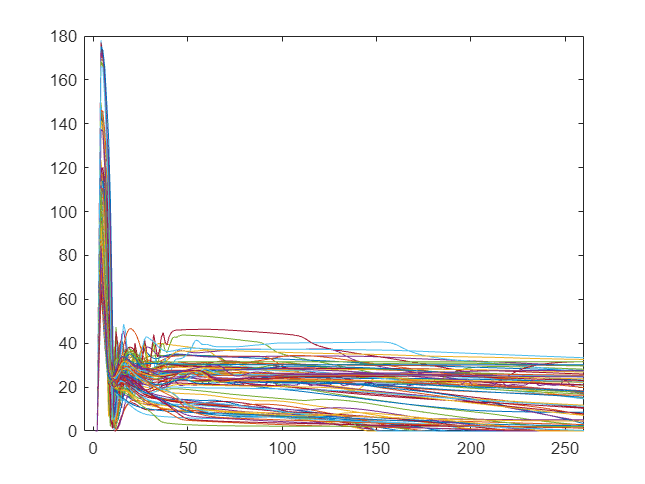

% disp=readmatrix('disp.csv');
% disp=disp(:,2:82);

force=readmatrix('force_lstm_force_time_relu.csv');
force=force(:,2:82);

for i = 1:81
    plot(force(:,i));
    hold on;
    xlim([-5,260])
end

fea_disp=readmatrix('lstm_full_81.xlsx', 'sheet','Disp')

fea_disp =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

fea_disp= fea_disp(1:400,:)

fea_disp =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


fea_force=readmatrix('lstm_full_81.xlsx', 'sheet','Force')

fea_force =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

fea_force= fea_force(1:400,:)

fea_force =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

avg_disp = sum(fea_disp,2)./81

avg_disp =          0
         0
    0.7753
    1.5506
    2.3259
    3.1012
    3.8765
    4.6518
    5.4271
    6.2024


hold off;

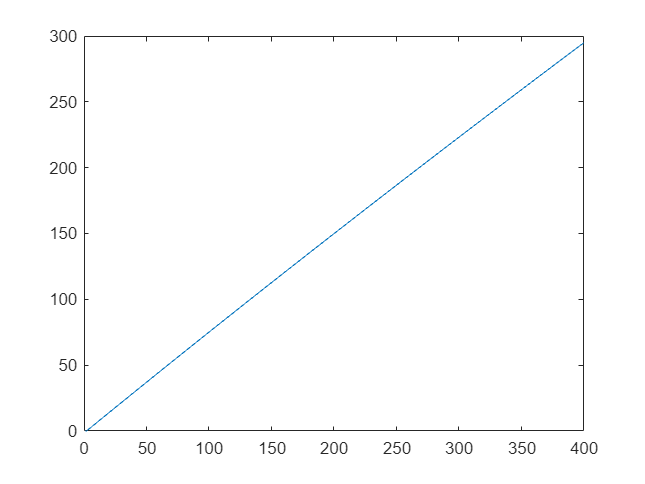

plot(avg_disp(:,1))

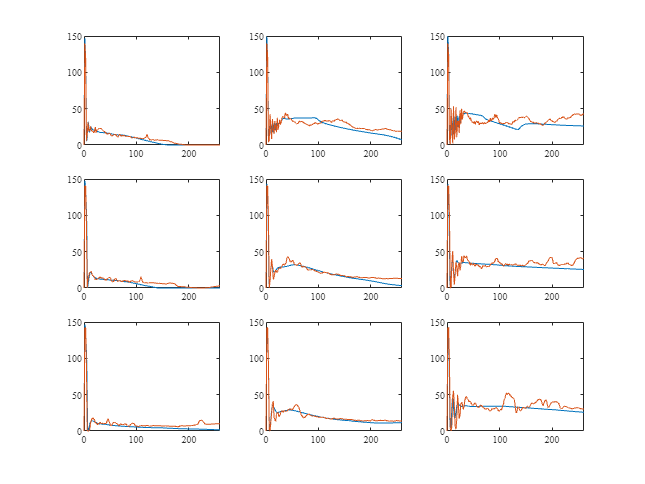

tiledlayout(3,3)
for i = 10:18
    nexttile
    plot(avg_disp(:,1),force(:,i))
    hold on;
    plot(fea_disp(:,i),fea_force(:,i))
    set(gca, 'FontName', 'Times New Roman','FontSize',6,'FontSmoothing', ...
    'on','LineWidth',1,'TickLength',[0.025 0.025])
    xlim([0 260])
end